# Test Live Script

## Noise Performance

NOTE: *# and letters are represented by their ascii values

% Almost noise free
generate(['0','1','2','3','4','5','6','7','8','9','A','B','C','D','*','#'], 500, -100 ,'numbers/noise_free.wav');

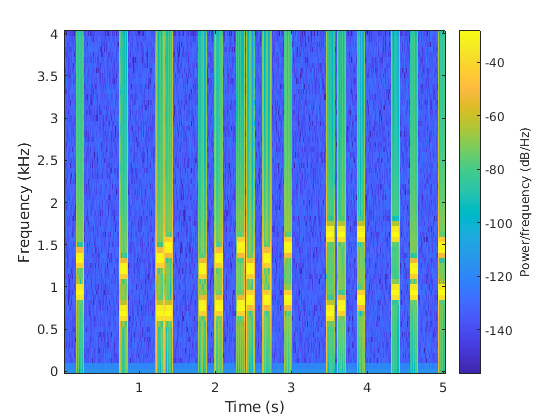

[signal, fs] = audioread("numbers/noise_free.wav");
figure(50);
spectrogram(signal,128,120,128,fs,'yaxis');

digits = detectDigits(signal,fs);
disp(digits')

     0     1     2     3     3     4     5     6     7     7     8     9    65    66    67    68    42    35



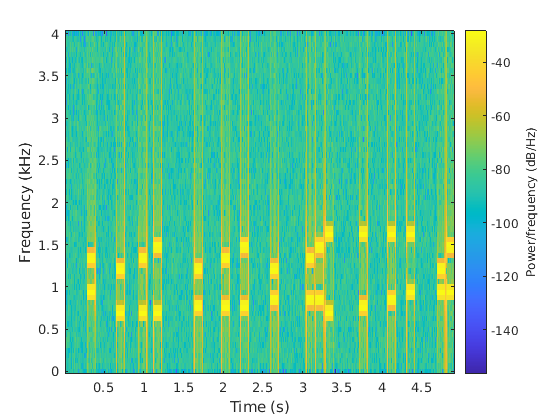

% Moderate Noise
generate(['0','1','2','3','4','5','6','7','8','9','A','B','C','D','*','#'], 500, 0 ,'numbers/noise_0dbm.wav');
[signal, fs] = audioread("numbers/noise_0dbm.wav");
figure(500);
spectrogram(signal,128,120,128,fs,'yaxis');

digits = detectDigits(signal,fs);
disp(digits')

     0     1     2     3     4     5     6     7     8     9     9    65    65    66    67    68    42    35    35



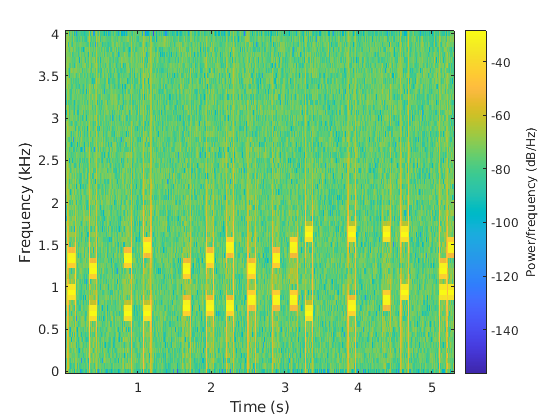

% High noise
generate(['0','1','2','3','4','5','6','7','8','9','A','B','C','D','*','#'], 500, 10,'numbers/noise_10dbm.wav');
[signal, fs] = audioread("numbers/noise_dbm.wav");
figure(500);
spectrogram(signal,128,120,128,fs,'yaxis');

digits = detectDigits(signal,fs);
disp(digits')

     0     1     2     0     3     0     4     5     6     5     7     4     8     9    65     3     7    66     1    67    68    42    35

